# Edge Detection Theory

[⇦ Main Menu](matlab:open('..\MainMenu.mlx'))

This script serves as an introduction to the theory behind edge detection. 

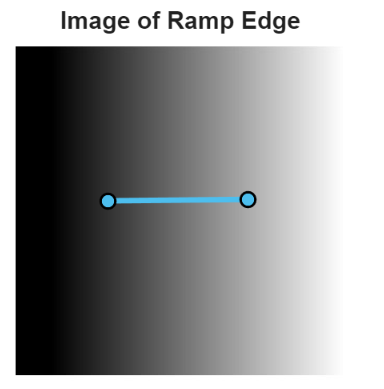

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What are Edges, and Why are Edges Important?

An edge is a boundary of connected pixels between two regions. Edges are crucial in computer vision and image processing for extracting information, recognizing objects, and recovering geometry and viewpoints from images. Edge detection is the initial step in segmenting images, particularly in simple scenes, to identify strong edges to extract useful information and transition from the original image to a processed one that includes outlines of objects.

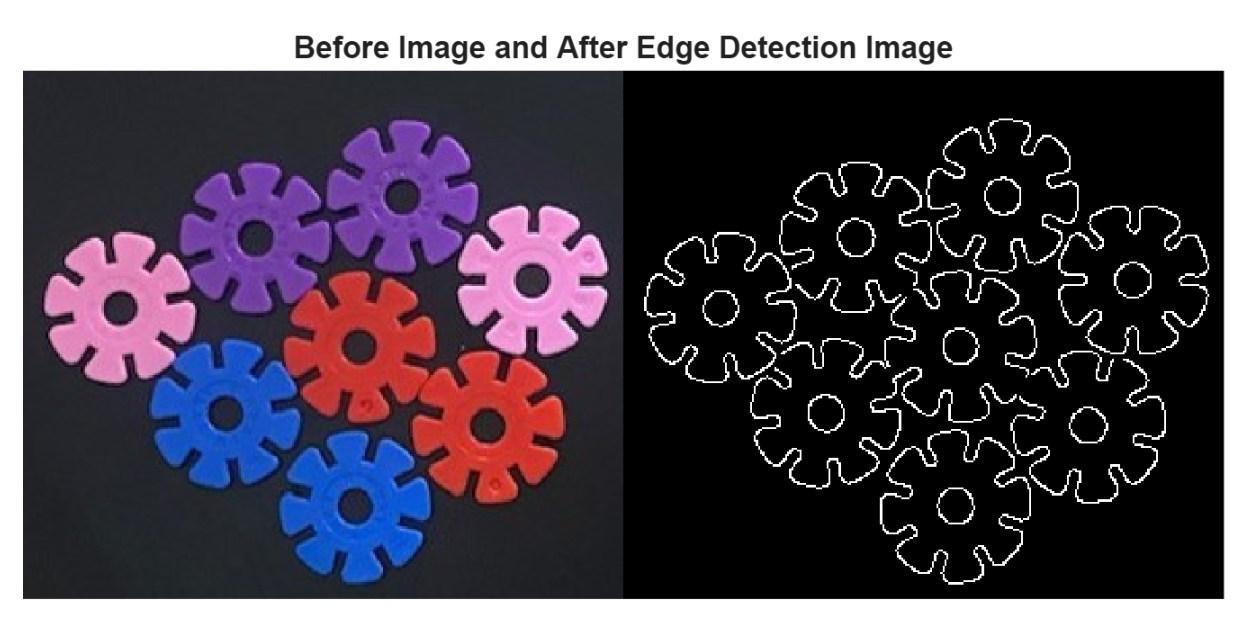

## Where do Edges Come From? 

Edges arise as a result of discontinuities in a variety of image properties including surface normal, depth, surface color, and illumination. 

- **Surface normal discontinuities **occur when there are sudden changes in surface orientation. For example, if you look at the cube below, at the edges where two faces meet, there is a discontinuous change in the direction of the surface normal. In everyday conversation, you would probably call this an edge.

- **Depth discontinuities **occur when there is an abrupt change in the distance between surfaces. If you look at the cube below, the back edge of the cube is significantly closer to the viewer than the background of the image—thus representing a depth discontinuity. 

- **Surface color discontinuities** occur when there is a change in color or intensity. Moving from the writing on the cube below to space on the cube without writing represents a surface color discontinuity. 

- **Illumination discontinuities** occur when there is an abrupt change in lighting. You can see the example of the illumination discontinuity from the shadow of the cube below.

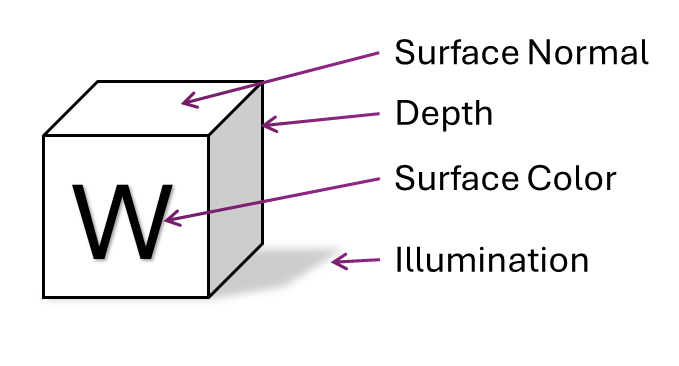 

## Characterizing Edges From Image Profiles (1D)

Each pixel in an image has an intensity value, and an edge is defined by an abrupt change in this intensity. By visualizing these edges and their corresponding image profiles, you can analyze the difficulty of identifying edges from these profiles. Simplified 1D analysis, which examines intensity changes along a single line of pixels, helps us understand basic edge properties without the complexity of 2D data.

There are four common edge models in images: step, ramp, line, and roof edges.

- **Step edges** occur when a light region is adjacent to a dark region. 

- **Line edges **occur when a thin line of light or dark occurs on a dark or light background. 

- **Roof edges** occur when the lightness rapidly increases and then decreases, or vice versa. 

- **Ramp edges** occur when the lightness gradually changes across a region.

  **Try**. Visualize the ideal edges in 2D and their corresponding image intensity profiles in 1D.

- *Select one of the four ideal edges from the drop-down menu below.*

- *Use the marker to select a segment that spans both the light and dark areas of the image.*

- *Repeat this process for each of the four ideal edges.*

IdealEdge ="Select";
if ~strcmp(IdealEdge,"Select")
    [Position,EdgeImage,ImageTitle]= GetPosition(IdealEdge,false); %#ok<*UNRCH>
  
    DrawProf(IdealEdge,EdgeImage,ImageTitle,Position);
else
    warning("Select a valid option.")
end

 **Reflect**. Compare and contrast the intensity profiles for the ideal images. 

### Detecting Edges Amid Noise

We have been looking at nearly perfect ideal edges, but what happens when we introduce noise? In this section, you will evaluate the 1D intensity profiles from 2D images of noisy edges.

  **Try**. Visualize the ideal edges with noise in 2D and their corresponding image intensity profiles in 1D.

- *Select one of the four ideal edges from the drop-down menu below.*

- *Use the marker to select a segment from the light to dark region of the image.*

- *Repeat this process for each of the four ideal edges.*

IdealEdge ="Select";
if ~strcmp(IdealEdge,"Select")
    [Position,EdgeImage,ImageTitle]= GetPosition(IdealEdge,true);
    DrawProf(IdealEdge,EdgeImage,ImageTitle,Position);
else
    warning("Select a valid option.")
end

 **Reflect**. Compare and contrast the level of difficulty of identifying the edge amid noise from the intensity profiles. 

### Using the First Derivative to Detect Edges (1D)

In calculus, the derivative of a continuous function represents its rate of change. Although intensity profiles are discrete rather than continuous, we can still compute a numerical derivative. In the numerical derivative of an intensity profile, sharp changes in intensity correspond to peaks of the first derivative. Sharp peaks correspond to strong edges and gradual peaks correspond to weak edges.

  **Try**. Visualize the derivative of the ideal edges and quantify the number of extrema (or edges).

- *Select one of the four ideal edges from the drop-down menu below.*

- *Use the button to visualize the first derivative of the intensity profile of your chosen edge.*

- *Repeat this process for each of the four ideal edges.*

option = "Select";
tSignal = linspace(-5,5,500);
PlotEdge(option,tSignal,"Derivative","WithDrawNow")

 **Exercise 1. **

For which case(s) of the idealized edges, does the 1D derivative-based edge-finding identify weak edges? 

**Solution:**

CheckAnswer("exercise1",[false false false false])% [step ramp line roof]
 

 **Exercise 2. **Based on the number of sharp peaks in the plot of the first derivative of the function how many strong edges are present in the plot below?

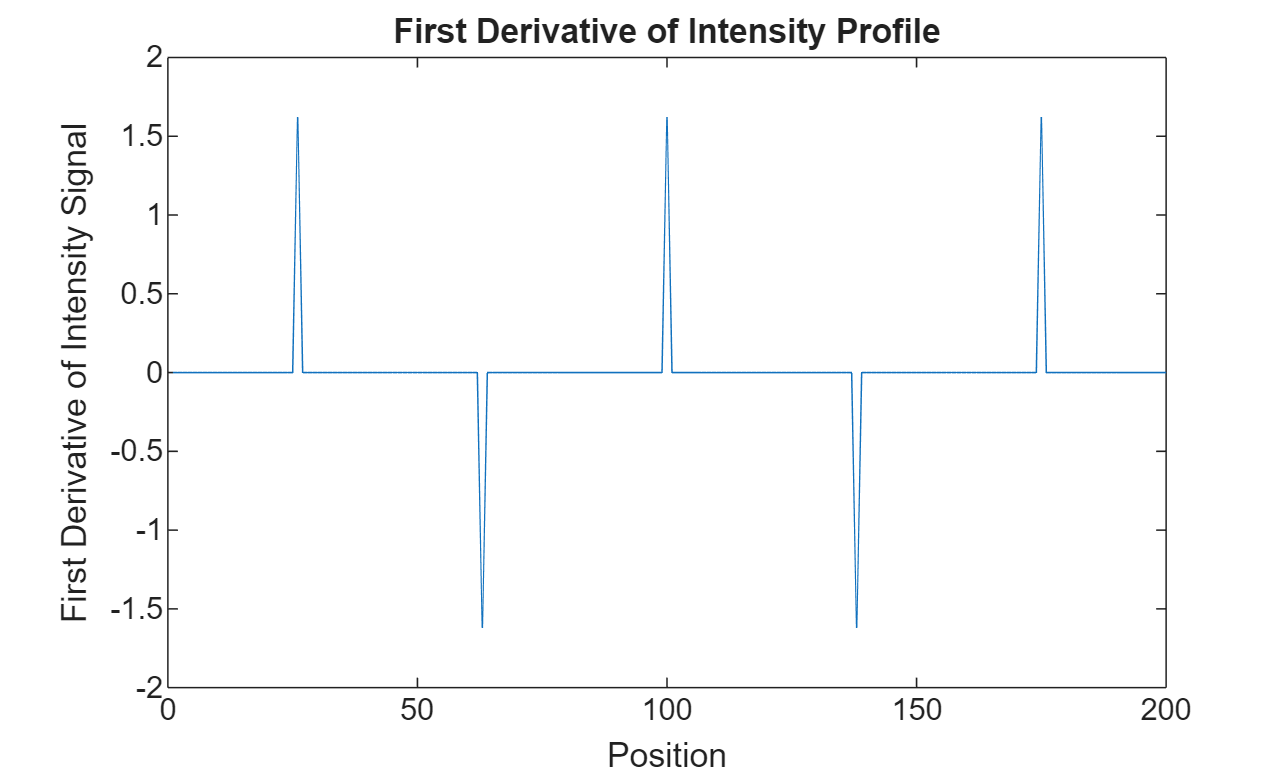

**Solution:**

CheckAnswer("exercise2",2)
 

### Using the First Derivative to Detect Edges Amid Noise (1D)

Recall from the Detecting Edges Amid Noise section above, that when we add noise the edge is more difficult to detect than in the original function. With noise, we have a lot of sharp peaks, but we want to distinguish between the true edges and the noise. To do this, we need to understand the concept of prominence, which measures how much a peak stands out from the surrounding data. This measurement is crucial for identifying significant edges. Let's look at the derivative of the 1D function and quantify the number of sharp peaks. 

   **Try**. Visualize the derivative of the ideal edges amid noise and quantify the number of sharp peaks (or edges).

- *Select one of the four ideal edges from the drop-down menu below.*

- *Use the button to visualize the first derivative of the intensity profile of your chosen edge.*

- *Repeat this process for each of the four ideal edges.*

  The threshold for noise has been adjusted to enable visualization.

option = "Select";
if option == "Select"
    warning("Select a valid option.");
    return
end
tSignal = linspace(-5,5,500);
NoisySignal = GenNoisySig(option,tSignal);
df = CalcDeriv(NoisySignal);

% Plot the original and noisy signals for comparison
plot(tSignal,CreateBaseSignal(option,tSignal),DisplayName="Original Signal",SeriesIndex=1)
hold on
plot(tSignal,NoisySignal,DisplayName="Noisy Signal",SeriesIndex=2)
hold off
legend(Location="bestoutside")
title("Original and Noisy Signals")
xlabel("Position")
ylabel("Intensity of Signal")

% Plot the derivative of the noisy signal
plot(tSignal(1:end-1),df,SeriesIndex=2,DisplayName="Derivative")
Threshold = 0.5;
[locsMax2,maxPeak2,locsMin2,minPeak2] = FindPeaks(df,Threshold); % Identify peak locations

% Plot the peaks
hold on
plot(tSignal(locsMax2),maxPeak2,"^",DisplayName="Positive Peak",SeriesIndex=3);
plot(tSignal(locsMin2),-minPeak2,"v",DisplayName="Negative Peak",SeriesIndex=4);
hold off

pks = nnz(maxPeak2)+nnz(minPeak2); % Calculate the total number of peaks

title("First Derivative of "+newline+option+" Noisy Signal")
xlabel("Position")
ylabel("First Derivative of Intensity Signal")
axis padded
legend(Location="bestoutside");
disp("Number of sharp peaks: "+pks)

### Handling Noise in Edge Detection (1D)

We can smooth the noise by convolving a Gaussian filter with the original signal. Notice as you increase the smoothing factor, you minimize the noise, but the edge becomes less prominent and more difficult to detect. 

  **Try**. Smooth noise using a Gaussian filter.

- *Adjust the smoothing factor value to smooth the signal to eliminate noise and quantify the number of extrema for the smoothed signal.*

- *Can you get the number of extrema to match the ideal signal without noise?*

option = 'Select';
if option == "Select" %#ok<*BDSCI>
    warning("Select a valid option.");
    return
end
tSignal2 = linspace(-5,5,500);
NoisySignal = GenNoisySig(option,tSignal2);
df2 =CalcDeriv(NoisySignal);

% Smooth input signal
[SmoothedData,winSize] = smoothdata(NoisySignal,"gaussian",SmoothingFactor=0.05); 
dfSmooth = diff(SmoothedData);
dfSmooth = dfSmooth/max(dfSmooth);

plot(tSignal2(1:end-1),df2,SeriesIndex=2,DisplayName="Noisy Derivative") % Plot original Derivative
hold on

% Find local maxima and minima
maxIndices3 = islocalmax(dfSmooth,MinProminence=1);
minIndices3 = islocalmin(dfSmooth,MinProminence=1);

% Display results
plot(tSignal2(1:end-1),dfSmooth,SeriesIndex=6,DisplayName="Smoothed Signal")
hold on

% Plot local maxima
scatter(tSignal2(maxIndices3),dfSmooth(maxIndices3),"^","filled",SeriesIndex=2,DisplayName="Positive Peak")

% Plot local minima
scatter(tSignal2(minIndices3),dfSmooth(minIndices3),"v","filled",SeriesIndex=3,DisplayName="Negative Peak")

title("First Derivative of Smoothed "+newline+option+ " Signal")
xlabel("Position")
ylabel("First Derivative of"+newline+"Intensity Signal")
axis padded
legend(Location="bestoutside")
hold off
pks = nnz(maxIndices3)+nnz(minIndices3); % Calculate the total number of peaks
disp("Number of sharp peak(s): " + pks)

** Application. **Use the first derivative to detect edges to identify the elbow bone in the X-ray image.

 
AppIm="XRayofArm.jpg";
[Position,EdgeImage,ImageTitle]= GetPosition(AppIm,false);
DrawProf(AppIm,EdgeImage,ImageTitle,Position);


### Using the Second Derivative to Detect Edges (1D)

In calculus, the second derivative measures how the rate of change of a function changes. For 1D signals, it reflects curvature or slope changes. Edges can be detected at **zero-crossings**, where the second derivative changes sign or crosses zero.

  **Try**. Visualize the second derivative of the ideal edges and quantify the number of **zero-crossings** (or edges).

option = "Select";
PlotEdge(option,tSignal,"SecondDerivative","WithDrawNow")

 **Exercise 3. **Based on the number of **zero-crossings** in the plot of the second derivative of the function, how many edges are present?

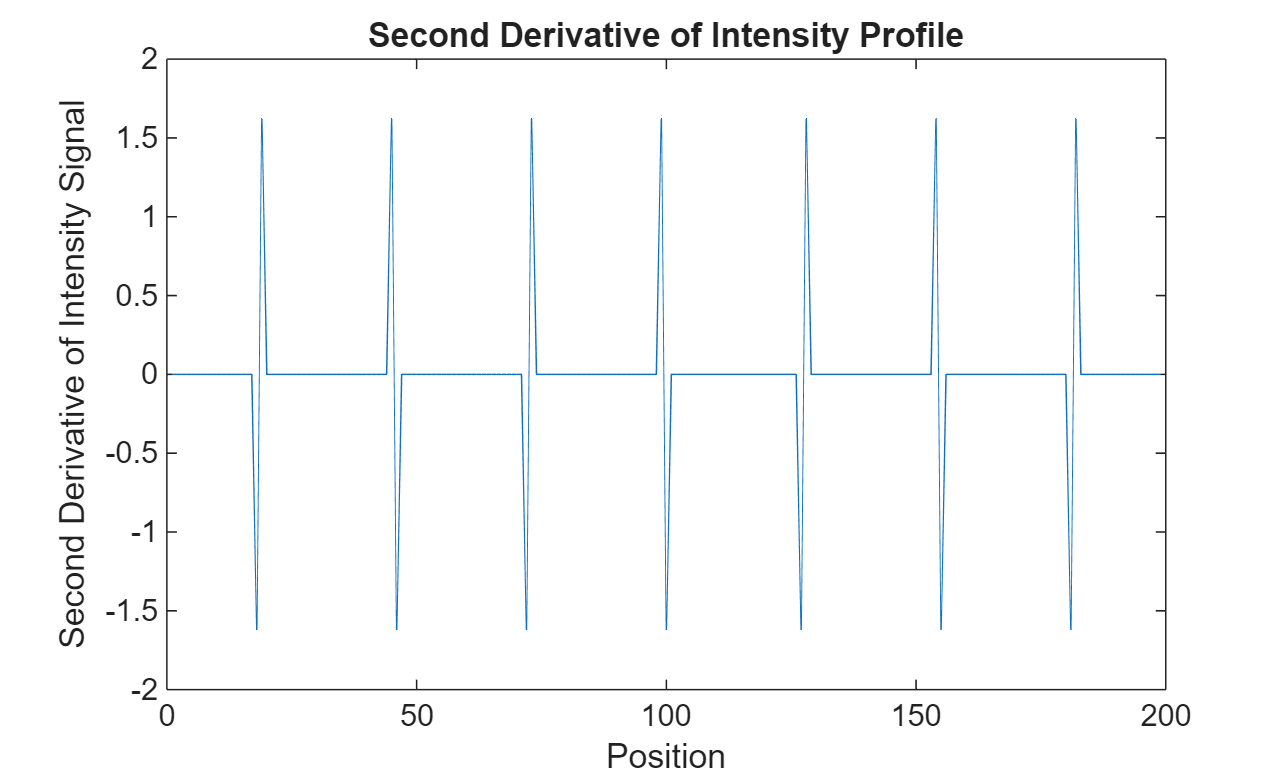

**Solution:**

CheckAnswer("exercise3",2); 

## Edge Detection by Gradients (2D)

We have used simplified 1D analysis to understand the basic location of edges and qualitatively determine the strength. Now, we'll focus on obtaining a more complete and accurate representation of images by quantifying the edge gradient vector, which provides both **edge strength** and **edge direction**. Since we typically work with 2D images, we don't usually analyze them from a 1D perspective of individual pixels or intensities.

Mathematically, for a function $f(x,y)$ the **gradient vector **,$\nabla f$, is given by:

    
$$\text{gradient vector} =\nabla f =\left[ \frac{\partial f}{\partial x} , \frac{\partial f}{\partial y} \right]




$$


The **gradient vector** of a 2D image represents the direction and rate of the most rapid intensity change at each pixel. It is composed of two components:

- gradient in the x-direction $\displaystyle \left(\frac{\partial f}{\partial x}\right)





$: This measures the change in intensity along the horizontal axis.

- gradient in the y-direction $\displaystyle \left(\frac{\partial f}{\partial y}\right)





$: This measures the change in intensity along the vertical axis.

In the image below, you will see the gradient vector drawn on the **ramp edge**. Notice the impact of gradient changes in the x and y-direction on the images. 

The **edge strength** is given by the magnitude of the **gradient vector**. A larger gradient magnitude signifies a steeper change at the edge, while a smaller magnitude suggests a more gradual change. For a **ramp edge**, the gradient might be less pronounced compared to a sharp edge, reflecting a gradual change in intensity. 


$$\text{edge strength}  = |\nabla f| = \sqrt{\left( \frac{\partial f}{\partial x} \right)^2 + \left( \frac{\partial f}{\partial y} \right)^2}
$$


The **edge direction** is given by the direction of the **gradient vector**, $\theta$, and points in the direction of the steepest intensity change. For a **step edge**, this direction is perpendicular to the edge itself. A large **edge direction** indicates a sharp transition between different areas in the image, such as the line between a dark object and a light background. In contrast, a small **edge direction **signifies a gradual transition between regions of lightness.


$$\text{edge direction}=\theta = \tan^{-1} { ~~\frac{\partial f}{\partial y}~~  \overwithdelims () {\frac{\partial f}{\partial x} }
$$


  **Try**. Compare the **edge strength** for the **step edge** and the **ramp edge**. 

- *Select an ideal edge image from the drop-down menu below.*

- *Use your mouse to draw a horizontal line across white to black regions of the image. *

Image ="Select";
if ~strcmp(Image,"Select")
    [Position,EdgeImage,ImageTitle]= GetPosition(Image,false);
    imshow(Image)
    hold on
    [Mag, Dir]=DrawGrad(Image,Position,"Static");
    title("The edge strength is "+round(Mag))
    hold off
else
    warning("Select a valid option.")
end

 **Reflect**.The gradient vector points in the direction of the fastest increase in intensity. How does the gradient relate to the direction of the edge?

** Application. **In medical imaging, diseases are often detected when clear edges are not visible. A weak edge might indicate disease, while a strong edge suggests health. Remember, the stronger the edge, the higher the likelihood of clear edge detection. Compare the **edge strength** in the two lung images below and determine which lung is more likely to be diseased.

** Demonstration**. Calculate the edge strength for the first lung image.

 
ImgApp1 = "LungA.jpg";
imshow(ImgApp1)
drawnow
hold on
Position1 = [180 595; 180 165];
[Mag1,Dir1]=DrawGrad(ImgApp1,Position1,"DrawNow");
hold off
title("The edge strength is "+round(Mag1))
disp(("Image Source: Mikael Häggström, M.D. Author info - Reusing images-" +newline+"Conflicts of interest: NoneMikael Häggström, M.D.Consent note: Written informed consent"+newline+" was obtained from the individual, including online publication., CC0, via Wikimedia Commons"+newline+sprintf('<a href="https://commons.wikimedia.org/wiki/File:chest_X-ray_in_influenza_and_Haemophilus_influenzae.jpg">X-Ray of Chest</a>')))

  **Try**. Calculate the edge strength for the second lung image.

- *Draw a vertical vector up the rib cage using the marker.*

 
ImgApp2 = "LungB.jpg";
imshow(ImgApp2)
[Position2,ImgApp2,ImageTitle] = GetPosition(ImgApp2,false);
imshow(ImgApp2)
hold on
[Mag2,Dir2]=DrawGrad(ImgApp2,Position2,"Static");
title("The edge strength is "+round(Mag2))
hold off
disp("Image Source: Mikael Häggström, M.D. Author info - Reusing images-" +newline+"Conflicts of interest: NoneMikael Häggström, M.D.Consent note: Written informed consent was obtained from the individual, including online publication., CC0, via Wikimedia Commons"+newline+" was obtained from the individual, including online publication., CC0, via Wikimedia Commons"+newline+sprintf('<a href="https://commons.wikimedia.org/wiki/File:Chest_X-ray_in_influenza_and_Haemophilus_influenzae.jpg">X-Ray of Chest</a>'))

## Glossary

**edge direction**: the orientation or angle of an edge in an image. It indicates the direction in which the intensity changes most rapidly, helping to understand the structure and shape of objects within the image. (↑ Return to Text)

**edge strength**: the measure of the intensity or sharpness of a boundary between different regions in an image. It quantifies how distinct or pronounced the transition is from one area to another. (↑ Return to Text)

**gradient vector:** a vector that points in the direction of the greatest rate of increase of a function. (↑ Return to Text)

**zero-crossings**: the points in a signal or function where the value changes sign, crossing from positive to negative or vice versa. (↑ Return to Text)

## Further Exploration

*Learn the fundamentals of convolutions in *[Convolution in Digital Signal Processing](https://www.mathworks.com/matlabcentral/fileexchange/97112-convolution-in-digital-signal-processing).

[⇦ Return to the main menu](matlab:open('..\MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function PlotEdge(option,tSignal,PlotType,RealTimeMode)
% Function to generate Ideal Edges (1D)
% Inputs:
% option - ("Step Edge","Ramp Edge","Line Edge","Roof Edge","Select")
% plot_type - ("Signal","Derivative","SecondDerivative")
% RealTimeMode - ("WithDrawNow" or "WithoutDrawNow") for different real-time plotting behaviors

signal=CreateBaseSignal(option,tSignal); % Create base signal

if ~strcmpi(option,"Select")
    t = tSignal;
    % Calculate Derivatives
    f = signal/max(signal);
    df = diff(f);
    df = df/max(df);
    ddf = diff(df);
    ddf = ddf/max(ddf);

    if strcmpi(PlotType,"Derivative") % Plot the original function and then active plot the First Derivative
        % Plot the Original Function
        sc = scatter(t(1),signal(1),"o",DisplayName="",SeriesIndex=1);
        hold on
        pt = plot(t(1),signal(1), "DisplayName","Signal");
        legend(Location="bestoutside");
        hold off

        % Set the axis limits
        axis padded
        if ~strcmp(option,"Line Edge")&&~strcmp(option,"Roof Edge")
            axis([-5 5 -0.2 1.2]);
        else
            axis([-5 5 -1.2 1.2]);
        end

        for i = 2:length(t)
            % Update the scatter and plot data for the signal
            sc.XData = t(i);
            sc.YData = signal(i);
            pt.XData(end+1) = t(i);
            pt.YData(end+1) = signal(i);
            title(["The " option " Signal"])
            xlabel("Position")
            ylabel("Intensity of Signal")
        end

        % Plot the First Derivative
        hold on
        scdf = scatter(t(1), df(1),"o",DisplayName="",SeriesIndex=5); % Moving scatter for derivative
        ptdf = plot(t(1),df(1),DisplayName="First Derivative",SeriesIndex=5); % Line for derivative
        hold off

        % Loop through data points
        drawnow
        title("First Derivative"+newline+" of the "+option+" Signal");
        ylabel("First Derivative of Intensity Signal")
        xlabel("Position")
        for i = 2:length(t)-1
            % Update derivative scatter and line
            scdf.XData = t(i);
            scdf.YData = df(i);

            % Retain the latest point of the original signal, clearing older ones
            sc.XData = t(i);
            sc.YData = signal(i);
            pt.XData(1) = []; % Remove oldest point
            pt.YData(1) = []; % Remove oldest point

            % Append to the derivative line plot
            ptdf.XData(end+1) = t(i);
            ptdf.YData(end+1) = df(i);

            % Update plot in real time (with extrema included)
            drawnow limitrate
        end
        % Define signal and threshold
        Threshold = 0.1;

        % Call function to find peaks
        [locsMax,maxPeak,locsMin,minPeak] = FindPeaks(df,Threshold);

        hold on;
        plot(tSignal(locsMax),maxPeak,"^",DisplayName="Positive Peak",SeriesIndex=3);
        plot(tSignal(locsMin),-minPeak,"v",DisplayName="Negative Peak",SeriesIndex=4);
        hold off;
        pks = nnz(maxPeak)+nnz(minPeak);
        disp("Number of sharp peak(s): "+pks)
    end
else
    return
end

if strcmpi(PlotType,"SecondDerivative")
    % Set the axis limits
    if ~strcmp(option, "Line Edge")&&~strcmp(option,"Roof Edge")
        axis([-5 5 -0.2 1.2]);
    else
        axis([-5 5 -1.2 1.2]);
    end

    % Plot the First Derivative
    scdf = scatter(t(1),df(1),"o",DisplayName="",SeriesIndex=5); % Moving scatter for derivative
    hold on
    ptdf = plot(t(1),df(1),DisplayName="First Derivative",SeriesIndex=5); % Line for derivative
    legend(Location="bestoutside");
    hold off

    % Loop through data points for first derivative
    for i = 2:length(t)-1
        % Update derivative scatter and line
        scdf.XData = t(i);
        scdf.YData = df(i);

        % Append to the derivative line plot
        ptdf.XData(end+1) = t(i);
        ptdf.YData(end+1) = df(i);

        % Update plot in real time (no extrema)
        title("The First Derivative"+newline+" of the "+option+" Signal");
    end

    % Plot the Second Derivative
    title("Second Derivative"+newline+" of the "+option+" Signal");
    hold on
    scddf = scatter(t(1),ddf(1),"o",DisplayName="",SeriesIndex=6); % Moving scatter for second derivative
    ptddf = plot(t(1),ddf(1),DisplayName="Second Derivative",SeriesIndex=6); % Line for second derivative
    hold off
    % Adjust the loop range to account for the length of ddf
    for i = 2:length(ddf) % Use the length of ddf instead of t
        % Update second derivative scatter and line
        scddf.XData = t(i);
        scddf.YData = ddf(i);

        % Append to the second derivative line plot
        ptddf.XData(end+1) = t(i);
        ptddf.YData(end+1) = ddf(i);

        % Update plot in real time (with zero crossings included)
        drawnow limitrate
    end
    drawnow
    % Detect Zero-crossings
    ZeroCrossings = sum(abs(ddf(1:end-1))>0.01&abs(ddf(2:end))>0.01&ddf(1:end-1).*ddf(2:end)<0); % Count zero crossings with threshold

    if ZeroCrossings>0
        zeroCrossingIndices = find(ddf(1:end-1).*ddf(2:end)< 0);
        hold on
        scatter(t(zeroCrossingIndices),zeros(size(zeroCrossingIndices)),"x",DisplayName="Zero-Crossings");
        legend(Location="bestoutside");
        hold off
        drawnow limitrate
    else
        ZeroCrossings = 0;
    end

    % Display the result
    disp("Number of zero-crossings: "+ZeroCrossings)

    % Cleanup temporary scatter and plot objects
    delete(scdf)
    delete(ptdf)
    delete(scddf)
end
end

function signal = CreateBaseSignal(option,tSignal)
arguments
    option (1,1) string {mustBeMember(option,["Step Edge" "Ramp Edge" "Line Edge" "Roof Edge" "Select"])}
    tSignal (1,:) double
end
% tSignal = linspace(-5, 5, 500);
% Select the signal based on the "option" parameter
switch option
    case "Step Edge"
        unitstep = double(tSignal >= 0); % Step Edge
        signal = unitstep/max(unitstep);
    case "Ramp Edge"
        ramp = (tSignal/5).* double(tSignal >= 0); % Ramp Edge
        signal = ramp/max(ramp);
    case "Line Edge"
        t1 = -0.5; t2 = 0.5;
        LineEdge = (tSignal >= t1)&(tSignal <= t2); % Line Edge
        signal = LineEdge/max(LineEdge);
    case "Roof Edge"
        t3 = -2.5; 
        t4 = 2.5;
        roof = zeros(size(tSignal));
        roof(tSignal >= t3 & tSignal < 0) = (tSignal(tSignal >= t3 & tSignal < 0) - t3) / (0 - t3);
        roof(tSignal >= 0 & tSignal <= t4) = (t4 - tSignal(tSignal >= 0 & tSignal <= t4)) / (t4 - 0);
        signal = roof/max(roof);
    case "Select"
        warning("Select a valid option.")
        signal = zeros(size(tSignal));
end
end


function CheckAnswer(exerciseID, option)
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
    "exercise1", struct("answer",[0 1 0 1],"hint","Which derivatives gradual peaks?"),...
    "exercise2", struct("answer",5,"hint","How many extrema are present?"),...
    "exercise3", struct("answer",7,"hint","How many zero-crossings are present?"),...
    "select", struct("answer","Select","hint","") ...
    );
% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        disp("You are correct.");
    else
        warning("%s",hint);
    end
else
    warning("Exercise not found.");
end
end

function NoisySignal = GenNoisySig(option,tSignal)
% Add noise to the signal
signal = CreateBaseSignal(option,tSignal); % Create base signal

% Add Gaussian noise to the signal
NoisySignal = signal+0.1*randn(size(signal));
end

function df = CalcDeriv(signal) % Function to calculate the derivative of an input signal
% Calculate numerical derivative
df = diff(signal);
df = df/max(df);
end

function [locsMax2, maxPeak2, locsMin2, minPeak2] = FindPeaks(df, Threshold)
% Find local maxima and minima
[maxPeak2,locsMax2] = findpeaks(df,Threshold=Threshold);
[minPeak2,locsMin2] = findpeaks(-df,Threshold=Threshold);
end

function DrawProf(IdealEdge,EdgeImage,ImageTitle,Position) %#ok<*INUSD> % Function to call drawline

% Define two positions from the drawn line
Position1 = Position(1,:); % First position [x1, y1]
Position2 = Position(2,:); % Second position [x2, y2]

% Display the image with the selected line
figure;
% IdealEdge=imread(IdealEdge);
imshow(EdgeImage);
title("Image of "+ImageTitle);
hold on;
drawline(Position = [Position1; Position2],Color=[0.3010 0.7450 0.9330]);
hold off;
if contains(ImageTitle, "Arm")
    disp("Image Source: Mikael Häggström, M.D. Author info - Reusing images-" + newline + "Conflicts of interest: NoneMikael Häggström, M.D., CC0, via Wikimedia Commons" + newline + sprintf('<a href="https://commons.wikimedia.org/wiki/File:X-ray_of_normal_elbow_by_lateral_projection.jpg">X-ray of normal elbow</a>'))
end
% Extract and plot the intensity profile along the line
figure;
ImProf = improfile(EdgeImage,Position(:,1),Position(:,2));
plot(ImProf(:,:,1));
xlabel("Position");
ylabel("Intensity Signal");
title("Intensity Signal of "+ImageTitle)

% Adjust axis limits
ax = gca;
ax.XLim = [1,length(ImProf(:,:,1))];
padding = 0.1*range(ImProf(:,:,1));
ax.YLim = [min(ImProf(:,:,1))-padding,max(ImProf(:,:,1))+padding];
end

function [magnitude, direction]=DrawGrad(EdgeImage,Position,DrawRealTime) % Function to calculate and draw gradient - This function can probably be part of the script.
% EdgeImage -The edge image picture
% Position -The position coordinates
% DrawRealtime - "DrawNow" or "Static"
% Define two positions from the drawn line
Position1 = Position(1,:); % First position [x1, y1]
Position2 = Position(2,:); % Second position [x2, y2]

fx = Position2(1)-Position1(1); % Change in x=(x2-x1)
fy = Position2(2)-Position1(2); % Change in y=(y2-y1)

% Calculate the magnitude of the vector
magnitude = norm([fx,fy]);

% Calculate the direction (angle) of the vector in radians
direction = atan2(fy,fx); % Direction in radians
direction = abs(direction*(180/pi)); % Direction in degrees

if strcmp(DrawRealTime,"DrawNow")
    % Animate the drawing of the line from Position1 to Position2
    numFrames = 200; % Number of frames for the animation

    prevX = Position1(1);
    prevY = Position1(2);
    % Animate the line
    for t = 1:numFrames
        % Compute current position
        currentX = Position1(1) + (fx * t / numFrames);
        currentY = Position1(2) + (fy * t / numFrames);

        % Draw the growing line
        drawline("Position",[Position1(1),Position1(2); currentX, currentY],Color=[0.3010 0.7450 0.9330]);

        % Update figure
        drawnow limitrate

        % Store previous position only in the last iteration
        if t == numFrames - 1
            prevX = currentX; %#ok<*NASGU>
            prevY = currentY;
        end
    end
else
end
% Compute the step displacement for quiver
quiver(Position1(1),Position1(2), fx, fy, 0, LineWidth=2,SeriesIndex=6,MaxHeadSize= 0.5);

end
